clear
nodepos = load('hasab_issues\Np.mat').Np;
shearrates = load('hasab_issues\Shearrate.mat').SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load('hasab_issues\Tnode.mat').Tnode;
fillstatus = load('hasab_issues\Fillstatus.mat').Fillstatus;
connectednodes = load('hasab_issues\connectedNodes.mat').connectedNodes;
connectedelements = load('hasab_issues\connectedElements.mat').connectedElements;

% Mapping the shearrates and temperatures at the nodes to the elements
elementnodeids = connectednodes + 1; % +1 so that indexing will work
elementshearrates = getElementValues(elementnodeids, shearrates);
elementtemps = getElementValues(elementnodeids, temps);
elementnodesfilled = getElementValues(elementnodeids, fillstatus);

% Calculating shearrate and temperature differences within the elements
sheardiffs = calcElementDiffs(elementshearrates);
tempdiffs = calcElementDiffs(elementtemps);

% Calculating element fill status
elementfillstatus = calcElementFillstatus(elementnodesfilled);

% Mapping the coordinates of the centorids of the elements to the elements
elementcoordinates = zeros(size(elementnodeids, 1), 3);
for i = 1:size(elementnodeids, 1)
    columnids = elementnodeids(i, :);
    x = mean(nodepos(columnids, 1));
    y = mean(nodepos(columnids, 2));
    z = mean(nodepos(columnids, 3));
    elementcoordinates(i, :) = [x, y, z];
end
%elementcoordinates

[highsheardiffs, normalsheardiffs, highsheardiffsbytimestep] = calcHighDiffElements(elementfillstatus, sheardiffs, 2);

dummy_torefine = transpose(1:10)

dummy_torefine =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


% Create matrix mapping edges to elements
edges = nchoosek(1:size(elementnodeids, 2), 2);
edges = transpose(edges);
edges = reshape(edges, [1, 12]);
elementedges = elementnodeids(:, edges);
elementedges = reshape(transpose(elementedges),  2, 6, []);
elementedges = permute(elementedges, [2, 1, 3]);
% Choose the edges to refine based on elements chosen for refinement
edgestorefine = elementedges(:, :, highsheardiffs(:, 1));
edgestorefine = permute(edgestorefine, [2, 1, 3]);
edgestorefine = transpose(reshape(edgestorefine, 2, []));
% Remove duplicate rows
edgestorefine_orig = edgestorefine;
edgestorefine = unique(sort(edgestorefine, 2), 'rows', 'stable'); % sorting edgestorefine so that edges like 1-2 and 2-1 will be treated as one
% Get coordinates of the nodes of the edges
X = nodepos(:, 1);
Y = nodepos(:, 2);
Z = nodepos(:, 3);
refine_X = X(edgestorefine);
refine_Y = Y(edgestorefine);
refine_Z = Z(edgestorefine);
% Calculate the coordinates of the new nodes
new_X = mean(refine_X, 2);
new_Y = mean(refine_Y, 2);
new_Z = mean(refine_Z, 2);
newnodes = [new_X, new_Y, new_Z];
newnodeids = transpose(size(nodepos, 1)+1:size(nodepos, 1)+size(newnodes, 1));
% Affected elements -> their edges (sorted) -> newly created nodes ->
% delaunay-triang.
elementedges_linear = sort(transpose(reshape(permute(elementedges, [2, 1, 3]), 2, [])), 2);
affectedelements = unique(ceil(find(ismember(elementedges_linear, edgestorefine, 'rows')) / size(elementedges, 1))); % ebben van a hiba

% Reconnect the vertices and the new points in all affected elements with
% delaunay-triangulation
tic
newconnectivity = cell(size(affectedelements, 1), 1);
for i=1:size(affectedelements, 1)
    % Get hold of the edges and nodes of the current element
    elementedges_current = sort(elementedges(:, :, affectedelements(i)), 2);
    elementnodes_current = unique(reshape(elementedges_current, [], 1));
    elementpoints_current = nodepos(elementnodes_current ,:);
    % Get hold of the respective new nodes to the current element
    newnodeindices_current = find(ismember(edgestorefine, elementedges_current, 'rows'));
    newpoints_current = newnodes(newnodeindices_current, :);
    newnodes_current = newnodeids(newnodeindices_current, :);
    allpoints_current = [elementpoints_current; newpoints_current];
    allnodes_current = [elementnodes_current; newnodes_current];
    DT = delaunayn(allpoints_current);
    %DT_ = delaunay(allpoints_current);
    newconnectivity_current = allnodes_current(DT);
    newconnectivity(i) = {newconnectivity_current};
end
toc

Elapsed time is 0.561424 seconds.



% Creating the new connectivity matrix
newconnectivity = cell2mat(newconnectivity);
newelementnodeids = elementnodeids;
% Removing refined elements
newelementnodeids(affectedelements, :) = [];
% Adding new elements
newelementnodeids = [newelementnodeids; newconnectivity];
% Adding new node positions
newnodepos = [nodepos; newnodes];

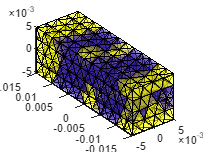

affectedelements_disp = affectedelements(find(~ismember(affectedelements, dummy_torefine(:, 1))));

colorvector = zeros(size(elementnodeids, 1), 1);
colorvector(dummy_torefine) = 1;
colorvector(affectedelements_disp) = 2;

tetramesh(elementnodeids, nodepos, colorvector, 'FaceAlpha',0.3)

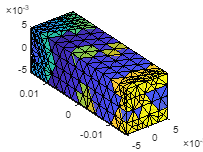

tetramesh(newelementnodeids, newnodepos)

createUDM(newnodepos, newelementnodeids, "hasab_1.udm")


affectedelements_disp = affectedelements(find(~ismember(affectedelements, highsheardiffs(:, 1))));
unchangedelements_disp = normalsheardiffs(find(~ismember(normalsheardiffs, affectedelements)))

unchangedelements_disp =      9   303   337   339   342   343   344   345   346   361   362   363   364   365   366   367   368   371   372   373   374   376   378   380   381   382   383   384   434   449   451   455   457   460   461   463   475   476   488   490   497   498   499   500   508   509   511   512   514   515


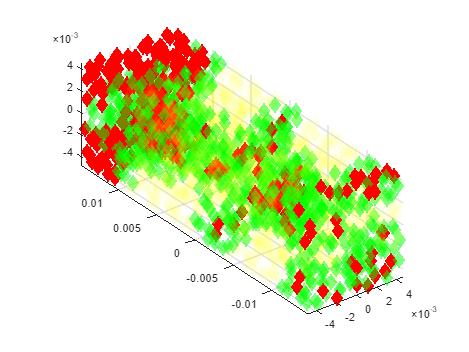

 
x = elementcoordinates(:, 1);
y = elementcoordinates(:, 2);
z = elementcoordinates(:, 3);

scatter3(x(highsheardiffs(:, 1)), y(highsheardiffs(:, 1)), z(highsheardiffs(:, 1)), 100, "filled", "d", "red")
hold on
scatter3(x(affectedelements_disp), y(affectedelements_disp), z(affectedelements_disp), 100, 'filled', 'd', 'green', 'MarkerFaceAlpha', 0.5,'MarkerEdgeAlpha', 0.8)
scatter3(x(unchangedelements_disp), y(unchangedelements_disp), z(unchangedelements_disp), 100,  "filled", "d","y", 'MarkerFaceAlpha', 0.1,'MarkerEdgeAlpha', 0.2)
axis equal
hold off


% Find the edges to refine
% edges_to_refine = [];
% refineelementnodes = [highsheardiffs(:, 1), elementnodeids(highsheardiffs(:, 1), :)];
% for i = 1:size(highsheardiffs(:, 1))
%     elementnodes = elementnodeids(highsheardiffs(i, 1), :);
%     elementnodecoords = nodepos(elementnodes, :);
%     elementvalues = shearrates(highsheardiffs(i, 2), elementnodes(:));
%     edges = nchoosek(1:length(elementvalues), 2);
%     edgenodes = elementnodes(edges);
%     edges_t = transpose(edges);
%     pair_values = elementvalues(edges);
%     relativeedgediffs = abs(diff(pair_values, 1, 2)) / sum(abs(diff(pair_values, 1, 2)));
%     edgecoords = elementnodecoords(edges_t(:, :), :);
%     [max_val, edgepos] = max(relativeedgediffs);
%     edgetorefine = edgenodes(edgepos, :);
%     edgetorefine = [highsheardiffs(i, 1), edgetorefine];
%     edges_to_refine = [edges_to_refine; edgetorefine];
% end
% 
% edges_to_refine = edges_to_refine(:, 2:3);

% Map the edges to refine to the elements they belong to
% edgeelements = cell(size(edges_to_refine, 1), 1);
% for i=1:size(edges_to_refine, 1)
%     indices = find(all(elementedges == edges_to_refine(i, :), 2));
%     elements = ceil(indices / size(elementedges, 1));
%     edgeelements(i) = {elements};
% end

% Itt folytatni majd


function elementvalues = getElementValues(elementnodeids, values) % Function for mapping node values to elements
    elementvalues = zeros(size(elementnodeids, 1), size(elementnodeids, 2), size(values, 1));
    for i = 1:size(elementnodeids, 1)
        columnids = elementnodeids(i, :);
        currentvalues = values(:, columnids);
        elementvalues(i, :, :) = currentvalues';
    end
end


% Function for calculating de diffs in the elements
function elementdiffs = calcElementDiffs(elementvalues)
    elementdiffs = (max(elementvalues, [], 2) - min(elementvalues, [], 2)) ./ abs(mean(elementvalues, 2));%table2array(rowfun(@(x) max(x) - min(x), table(elementvalues)));
    elementdiffs = reshape(elementdiffs, size(elementdiffs, 1), size(elementdiffs, 3));
    elementdiffs(isnan(elementdiffs)) = 0;
end


% Function for calculating the fillstatus in the elements possible node
% values of 3 and 4 are ignored because they are not present in the data
% and will likely not be used anyways
function elementfillstatus = calcElementFillstatus(elementvalues)
    elementfillstatus = zeros(size(elementvalues, 1), size(elementvalues, 3));
    for i = 1:size(elementvalues, 1)
        for j = 1:size(elementvalues, 3)
            if all(elementvalues(i, :, j) == 0)
                elementfillstatus(i, j) = 1;
            else
                elementfillstatus(i, j) = 0;
            end
        end
    end
end


% Function for separating the indices of filled and empty elements for
% every timestep
function [filledelements, emptyelements] = getFilledElements(elementfillstatus)
    filledelements = cell(1, size(elementfillstatus, 2));
    emptyelements = cell(1, size(elementfillstatus, 2));
    
    for i = 1:size(elementfillstatus, 2)
        filledindices = find(elementfillstatus(:, i) >= 1);
        emptyindices = find(elementfillstatus(:, i) < 1);
        filledelements{i} = filledindices;
        emptyelements{i} = emptyindices;
    end
end


% Function for retrieving elements with high diff values, the normal
% elements and a cell containing the highdiff elements by timestep - this
% might be removed if there is no need for use
function [highdiffelements, normalelements, highdiffsbytimestep] = calcHighDiffElements(elementfillstatus, results, thresholdfactor)
    [filledelements, emptyelements] = getFilledElements(elementfillstatus);

    highdiffelements = [];
    highdiffsbytimestep = cell(1, size(results, 2));

    for i = 1:size(results,2)
        threshold = thresholdfactor * mean(nonzeros(results(filledelements{i}, i)));
        highdiffs = find(results(filledelements{i}, i) > threshold);
        newelements = highdiffs(~ismember(highdiffs, highdiffelements));
        timestepatregister = zeros(size(newelements)) + i;
        newelements = [newelements, timestepatregister];
        highdiffelements = [highdiffelements; newelements];
        highdiffsbytimestep{i} = highdiffs;
    end
    allelementids = 1:size(results, 1);
    normalelements = allelementids(~ismember(allelementids, highdiffelements(:, 1)));
end


% Function for creating a new mesh by adding new nodes to the middle points
% of the edges of the elements
function [newnodepos, newelementnodeids] = createNewMeshMultiNode(highdiffelements, elementnodeids, nodepos)
    % Create matrix mapping edges to elements
    edges = nchoosek(1:size(elementnodeids, 2), 2);
    edges = transpose(edges);
    edges = reshape(edges, [1, 12]);
    elementedges = elementnodeids(:, edges);
    elementedges = reshape(transpose(elementedges),  2, 6, []);
    elementedges = permute(elementedges, [2, 1, 3]);
    % Choose the edges to refine based on elements chosen for refinement
    edgestorefine = elementedges(:, :, highdiffelements(:, 1));
    edgestorefine = permute(edgestorefine, [2, 1, 3]);
    edgestorefine = transpose(reshape(edgestorefine, 2, []));
    % Remove duplicate rows
    edgestorefine_orig = edgestorefine;
    edgestorefine = unique(sort(edgestorefine, 2), 'rows', 'stable'); % sorting edgestorefine so that edges like 1-2 and 2-1 will be treated as one
    % Get coordinates of the nodes of the edges
    X = nodepos(:, 1);
    Y = nodepos(:, 2);
    Z = nodepos(:, 3);
    refine_X = X(edgestorefine);
    refine_Y = Y(edgestorefine);
    refine_Z = Z(edgestorefine);
    % Calculate the coordinates of the new nodes
    new_X = mean(refine_X, 2);
    new_Y = mean(refine_Y, 2);
    new_Z = mean(refine_Z, 2);
    newnodes = [new_X, new_Y, new_Z];
    newnodeids = transpose(size(nodepos, 1)+1:size(nodepos, 1)+size(newnodes, 1));
    % Affected elements -> their edges (sorted) -> newly created nodes ->
    % delaunay-triang.
    elementedges_linear = sort(transpose(reshape(permute(elementedges, [2, 1, 3]), 2, [])), 2);
    affectedelements = unique(ceil(find(ismember(elementedges_linear, edgestorefine, 'rows')) / size(elementedges, 1)));
    
    % Reconnect the vertices and the new points in all affected elements with
    % delaunay-triangulation
    newconnectivity = cell(size(affectedelements, 1), 1);
    for i=1:size(affectedelements, 1)
        % Get hold of the edges and nodes of the current element
        elementedges_current = sort(elementedges(:, :, affectedelements(i)), 2);
        elementnodes_current = unique(reshape(elementedges_current, [], 1));
        elementpoints_current = nodepos(elementnodes_current ,:);
        % Get hold of the respective new nodes to the current element
        newnodeindices_current = find(ismember(edgestorefine, elementedges_current, 'rows'));
        newpoints_current = newnodes(newnodeindices_current, :);
        newnodes_current = newnodeids(newnodeindices_current, :);
        allpoints_current = [elementpoints_current; newpoints_current];
        allnodes_current = [elementnodes_current; newnodes_current];
        DT = delaunayn(allpoints_current);
        %DT_ = delaunay(allpoints_current);
        newconnectivity_current = allnodes_current(DT);
        newconnectivity(i) = {newconnectivity_current};
    end

    % Creating the new connectivity matrix
    newconnectivity = cell2mat(newconnectivity);
    newelementnodeids = elementnodeids;
    % Removing refined elements
    newelementnodeids(affectedelements, :) = [];
    % Adding new elements
    newelementnodeids = [newelementnodeids; newconnectivity];
    % Adding new node positions
    newnodepos = [nodepos; newnodes];
end


% Function for calculating the positions of new nodes in each
% highdiffelement
function [newnodes, newnodeids] = calcNewNodePos(highdiffelements, values, elementnodeids, nodepos)
    newnodes = [];
    newnodeids = [];
    nodeid = max(elementnodeids, [], "all");
    for i=1:size(highdiffelements, 1)
        nodeid = nodeid + 1;
        elementnodes = elementnodeids(highdiffelements(i, 1), :);
        elementnodecoords = nodepos(elementnodes, :);
        elementvalues = values(highdiffelements(i, 2), elementnodes(:));
        edges = nchoosek(1:length(elementvalues), 2);
        edges_t = transpose(edges);
        pair_values = elementvalues(edges);
        relativeedgediffs = abs(diff(pair_values, 1, 2)) / sum(abs(diff(pair_values, 1, 2)));   
        edgecoords = elementnodecoords(edges_t(:, :), :);
        edgecenters = transpose([mean(reshape(edgecoords(:, 1), 2, []), 1); mean(reshape(edgecoords(:, 2), 2, []), 1); mean(reshape(edgecoords(:, 3), 2, []), 1)]);
        centroid = [mean(elementnodecoords(:, 1)), mean(elementnodecoords(:, 2)), mean(elementnodecoords(:, 3))];
        vectors = edgecenters - centroid;
        %sumvector = 0.8 * (sum(vectors .* relativeedgediffs, 1));
        newnodepos = centroid; %+ sumvector;
        newnodes = [newnodes; newnodepos];
        newnodeids = [newnodeids;[elementnodes, nodeid]];
    end
end


% Function for creating the new node connections
function newnodeconnections = createNewNodeConnections(newnodeids)
    newnodeconnections = [];
    for i=1:size(newnodeids, 1)
        selections = nchoosek(1:length(newnodeids(i, 1:end-1)), size(newnodeids, 2)-2);
        selections = [selections, (zeros(size(selections, 1), 1) + max(selections, [], "all")+1)];
        newconnectivity = reshape(newnodeids(i, selections), size(selections));
        newnodeconnections = [newnodeconnections; newconnectivity];
    end
end


% Function for creating the entire new mesh with node positions and
% connectivity
function [newnodepos, newelementnodeids] = createNewMeshOneNode(highdiffelements, values, elementnodeids, nodepos)
    [newnodes, newnodeids] = calcNewNodePos(highdiffelements, values, elementnodeids, nodepos);
    newnodeconnections = createNewNodeConnections(newnodeids);
    % Creating complete new connectivity matrix
    newelementnodeids = elementnodeids;
    newelementnodeids(highdiffelements(1, :), :) = [];
    newelementnodeids = [newelementnodeids; newnodeconnections];
    % Appending new node positions to old ones
    newnodepos = [nodepos; newnodes];
end

% Function for creating the .udm file from the 
% Function for creating the .udm file from the node positions and
% connectivity matrix
function createUDM(newnodepos, newelementnodeids, filename)
    % This block of code generates the txt for the .udm file used for importing
    % the mesh into moldflow.
    
    node_ids = (1:size(newnodepos, 1)).';
    tetra_ids = (1:size(newelementnodeids, 1)).';
    
    % Title block
    title_str = sprintf(['TITL{\n  NAME{"Untitled"}\n  VRSN{"MOLDFLOW"}\n  KEYW{"1713296283"}\n' ...
                        '  DATE{"Apr-16-24"}\n  TIME{"21:38:03"}\n  UDMV{"UDM V3"}\n}']);
    
    % Summary block
    summary_str = sprintf(['SUMR{\n   NOCL{0}\n   NOLY{2}\n   NOTS{1}\n   NOVW{0}\n   NOND{%i}\n' ...
                           '   NOTX{0}\n   NO1D{0}\n   NOT3{0}\n   NOCV{0}\n   NOSF{0}\n   NORG{0}\n' ...
                           '   NONB{0}\n   NOSB{0}\n   NOCP{0}\n   NOLC{0}\n   NOT4{%i}\n}'], numel(node_ids), numel(tetra_ids));
    
    % Layer block
    layers_str = sprintf(['LYER{2 " HyperMesh Nodes" 0\n/* NODE */ 4 1 1 0 0\n/* TEXT */ 5 1 1 0 0\n' ...
                          '/* 1DET */ 6 1 1 0 0\n/* TRI3 */ 7 1 1 0 0\n/* CURV */ 8 1 1 0 0\n/* SURF */ 9 1 1 0 0\n' ...
                          '/* REGN */ 10 1 1 0 0\n/* NDBC */ 11 1 1 0 0\n/* SUBC */ 12 1 1 0 0\n/* LOCS */ 14 1 1 0 0\n' ...
                          '/* TET4 */ 15 1 1 0 0\n/* STLR */ 16 1 1 0 0\n}\n' ...
                          'LYER{4 "vol001" 1\n/* NODE */ 4 1 1 27 0\n/* TEXT */ 5 1 1 27 0\n/* 1DET */ 6 1 1 27 0\n' ...
                          '/* TRI3 */ 7 1 1 27 0\n/* CURV */ 8 1 1 27 0\n/* SURF */ 9 1 1 27 0\n/* REGN */ 10 1 1 27 0\n' ...
                          '/* NDBC */ 11 1 1 27 0\n/* SUBC */ 12 1 1 27 0\n/* LOCS */ 14 1 1 27 0\n/* TET4 */ 15 1 1 27 0\n' ...
                          '/* STLR */ 16 1 1 27 0\n}']);
    
    % Tset block
    tset_str = sprintf(['TSET{40000 1 "Injection location for thermoplastics processes (default)"\n  TCOD{770 ""\n   1.000000e+000}\n' ...
                        '  TCOD{772 ""\n  TCOD{773 ""\n  TCOD{774 ""\n  TCOD{775 ""\n  TCOD{20020 ""}\n  TCOD{20021 ""}\n  TCOD{20023 ""}\n' ...
                        '  TCOD{20032 ""}\n  1.000000e+004 1.000000e+000}\n  TCOD{20040 ""\n  3.001100e+004 1.000000e+000}\n  TCOD{20041 ""\n' ...
                        '  3.001300e+004 1.000000e+000}\n  TCOD{20046 ""\n  3.006000e+004 1.000000e+000}\n  TCOD{20060 ""\n  3.000700e+004 1.000000e+000}\n' ...
                        '  TCOD{20061 ""\n  3.000700e+004 1.000000e+000}\n  TCOD{30503 ""\n  1.000000e+000}\n  TCOD{30504 ""\n  1.000000e+008}\n  TCOD{30505 ""\n' ...
                        '  1.400000e+008}\n  TCOD{30506 ""\n  5.493604e+007}\n  TCOD{30510 ""\n  5.000000e+004 1.000000e+000}\n  TCOD{30520 ""\n  5.001000e+004 1.000000e+000}\n' ...
                        '  TCOD{30530 ""\n  5.002000e+004 1.000000e+000}\n  TCOD{30540 ""\n  5.003000e+004 1.000000e+000}}\n//TSET CARD FOR COOLANT INLETS\n' ...
                        'TSET{40020 1 "Coolant inlet (default) #1"\nTCOD{11102 ""\n  1.666667e-004}\n  TCOD{11103 ""\n  3.000000e+000}\n  TCOD{11104 ""\n' ...
                        '  1.000000e+004}\n  TCOD{11105 ""\n  1.000000e+004}\n  TCOD{11106 ""\n  2.981500e+002}\n  TCOD{20022 ""}}\n TSET{50400 1 "darab  "\n' ...
                        '  TCOD{30107 ""\n        1 }\n  TCOD{925 ""\n        1 }\n  TCOD{11108 ""\n        0 }\n  TCOD{310 ""\n        0 }\n  TCOD{30108 ""\n' ...
	                    '        0 }\n  TCOD{926 ""\n        1 }\n}']);
    
    % Nodal data section
    % Generating nodes_str
    X = newnodepos(:, 1);
    Y = newnodepos(:, 2);
    Z = newnodepos(:, 3);
    
    node_str_base = 'NODE{%d 0 2 1 0.1  %e  %e  %e}';
    node_str_cell = cell(size(newnodepos, 1), 1);
     
    for i = 1:numel(node_ids)
        node_str_cell{i} = sprintf(node_str_base, node_ids(i), X(i), Y(i), Z(i));
    end
    
    nodes_str = strjoin(node_str_cell, newline);
    
    % Tetrahedron data section
    % Generating tetras_str
    node1 = newelementnodeids(:, 1);
    node2 = newelementnodeids(:, 2);
    node3 = newelementnodeids(:, 3);
    node4 = newelementnodeids(:, 4);
    
    tetra_str_base = 'TET4{%d 0 4 27 0 "" 50400 1%s%s%s%s}';
    tetra_str_cell = cell(size(newelementnodeids, 1), 1);
    
    for i = 1:numel(tetra_ids)
        space = ' ';
        node1str = [repelem(space, (8 - numel(num2str(node1(i))))) num2str(node1(i))];
        node2str = [repelem(space, (8 - numel(num2str(node2(i))))) num2str(node2(i))];
        node3str = [repelem(space, (8 - numel(num2str(node3(i))))) num2str(node3(i))];
        node4str = [repelem(space, (8 - numel(num2str(node4(i))))) num2str(node4(i))];
        tetra_str_cell{i} = sprintf(tetra_str_base, tetra_ids(i), node1str, node2str, node3str, node4str);
    end
    
    tetras_str = strjoin(tetra_str_cell, newline);
    
    end_str = sprintf('ENDF');
    
    complete_str = [title_str newline summary_str newline layers_str newline ...
        tset_str newline nodes_str newline tetras_str newline end_str];
    
    fid = fopen(filename, 'w');
    fprintf(fid, complete_str);
    fclose(fid);
end

% Below here are functions for handy data visualization
% Function for plotting results
function plotElementData(elementcoordinates, results, timestep, colorlimit)
    x = elementcoordinates(:, 1);
    y = elementcoordinates(:, 2);
    z = elementcoordinates(:, 3);

    scatter3(x, y, z, 20, results(:, timestep), "filled")
    axis equal
    if strcmp(colorlimit, 'yes')
        clim([min(results(:)), max(results(:))])
    end
    colorbar
end


% Function for plotting the filling method while also displaying the 
% element values for a feature in the filled region. The flowfront is
% considered as empty so element values in the flowfront are ignored
function plotFillElementData(elementcoordinates, elementfillstatus, results, timestep, colorlimit)
    [filledelements, emptyelements] = getFilledElements(elementfillstatus);

    x = elementcoordinates(:, 1);
    y = elementcoordinates(:, 2);
    z = elementcoordinates(:, 3);

    scatter3(x(filledelements{timestep}), y(filledelements{timestep}), z(filledelements{timestep}), 20, results(filledelements{timestep}, timestep), "filled", 'MarkerEdgeColor', 'none')
    if strcmp(colorlimit, 'yes')
        clim([min(results(:)), max(results(:))])
    end
    colorbar
    hold on
    scatter3(x(emptyelements{timestep}), y(emptyelements{timestep}), z(emptyelements{timestep}), 20, 'filled', 'w', 'MarkerFaceAlpha', 0.2,'MarkerEdgeAlpha', 0.2)
    axis equal
    hold off
end